## 仿真数据分析1

rms(out.PID)

ans = 51.8111

rms(out.OF)

ans = 8.1418

rms(out.ADRC)

ans = 8.8437

rms(out.PROPOSE)

ans = 0.3251


max(out.PID)

ans = 160.6649

max(out.OF)

ans = 24.1887

max(out.ADRC)

ans = 27.4217

max(out.PROPOSE)

ans = 0.5389


split_points = [5, 15, 20, 23, 35, 40, 45, 55] * Fs;
segments_length = diff([0; split_points(:); length(out.tout)]);

segments_PID = mat2cell(out.PID, segments_length, 1);
segments_OF = mat2cell(out.OF, segments_length, 1);
segments_ADRC = mat2cell(out.ADRC, segments_length, 1);
segments_PROPOSE = mat2cell(out.PROPOSE, segments_length, 1);

Tab = table();
Tab.Segment = (1:length(segments_PID))';
Tab.RMS_PID = cellfun(@rms, segments_PID);
Tab.PV_PID = cellfun(@max,segments_PID);
Tab.RMS_OF = cellfun(@rms, segments_OF);
Tab.PV_OF = cellfun(@max,segments_OF);
Tab.RMS_ADRC = cellfun(@rms, segments_ADRC);
Tab.PV_ADRC = cellfun(@max,segments_ADRC);
Tab.RMS_PROPOSE = cellfun(@rms, segments_PROPOSE);
Tab.PV_PROPOSE = cellfun(@max,segments_PROPOSE);

disp(Tab);

    Segment    RMS_PID    PV_PID    RMS_OF     PV_OF      RMS_ADRC    PV_ADRC    RMS_PROPOSE    PV_PROPOSE
    _______    _______    ______    ______    ________    ________    _______    ___________    __________

       1       112.47     160.66    16.379      24.189     18.949     27.422       0.22484       0.48361  
       2       52.014     94.233    2.1722      5.1607     9.1458     14.182       0.52433       0.53761  
       3       67.748     12.731    15.432       1.437      10.61     2.1965       0.33589       0.53887  
       4       48.861     87.614    10.534      16.262     9.0067     15.483      0.034987       0.10251  
       5        38.62     94.528    5.0744      15.363      6.949      16.59       0.31563       0.34004  
       6         34.7      17.67    7.4655    -0.93086     5.0781     3.7267       0.22966       0.33951  
       7       43.213     68.466    7.4143      11.607     7.9136     11.899         0.162       0.28769  
       8       18.162      32.01    

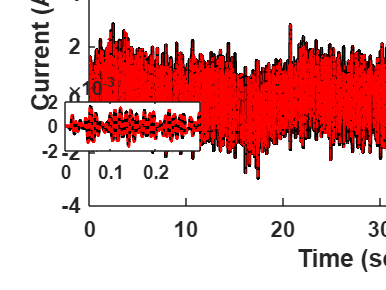

%% 电机电流
ylab1 = 'Current (A)';

choice = 1;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)./k_current,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)./k_current,'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-0.004,0.008])
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

a2 = axes('Position',[0.17 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice)./k_current,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)./k_current,'r:','LineWidth',2);
xlim(a2,[0,0.3]);
a2.FontWeight = 'bold';
a2.FontSize = 10;

xportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

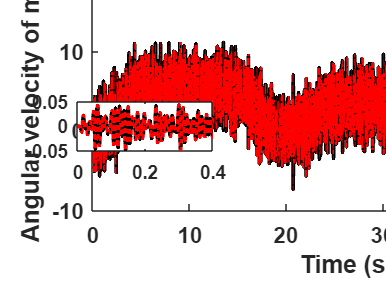

%% 电机转速
ylab1 = 'Angular velocity of motor (rad/s)';

choice = 2;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-0.1,0.3])
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;

a2 = axes('Position',[0.2 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r:','LineWidth',2);
xlim(a2,[0,0.4]);
a2.FontWeight = 'bold';
a2.FontSize = 10;

exportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

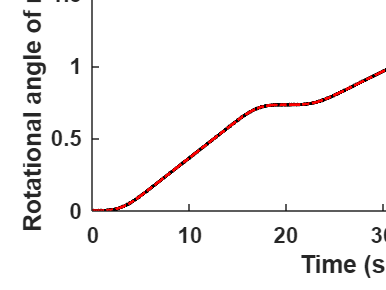

%% 电机转角
ylab1 = 'Rotational angle of motor (rad)';

choice = 3;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];
nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
ylim([0 2.2])
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

exportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

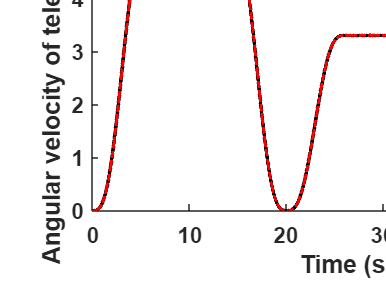

%% 望远镜转速
ylab1 = 'Angular velocity of telescope (rad/s)';

choice = 4;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');

xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;

exportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

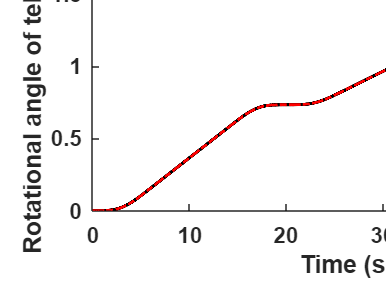

% 望远镜转角
ylab1 = 'Rotational angle of telescope (rad)';

choice = 5;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'real state','estimation','box','off');
ylim([0 2.2])
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

exportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

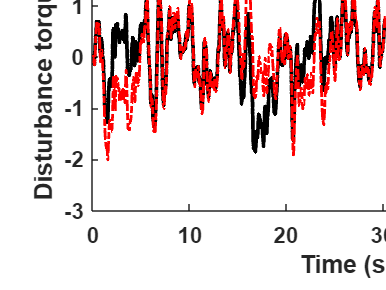

% 扰动观测
choice = 6;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
hold on;
p1 = plot(out.tout(1:end-1),out.dreal(1:end-1),'k','LineWidth',2);
p2 = plot(out.tout(1:end-1),out.dhat(1:end-1),'r-.','LineWidth',1.5);

legend([p1 p2],'real state','estimation','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel('Disturbance torque (N·m)','FontWeight','bold');
ylim([-300 320]);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = 2;

exportgraphics(gcf,fullfile('figures1', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

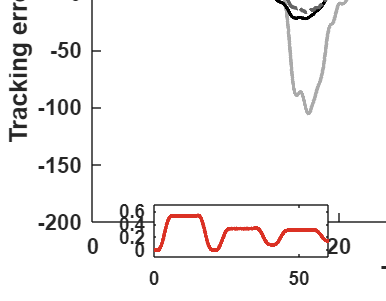

%% 跟踪误差对比图
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.Position = [1.75 1.5 14 8];

nexttile;
hold on;
p1 = plot(out.tout,out.PID,'k-','LineWidth',2,'Color',[170,170,170]/255);
p4 = plot(out.tout,out.PROPOSE,'-','LineWidth',2,'Color',[219, 49, 36]/255);
p3 = plot(out.tout,out.OF,'k-','LineWidth',2);
p2 = plot(out.tout,out.ADRC,'k-.','LineWidth',2,'Color',[100,100,100]/255);

ylim([-200 170]);
xlabel('Time (second)','FontWeight','bold');
ylabel('Tracking error (arcsec)','FontWeight','bold');
legend([p1,p2,p3,p4],'PID','ADRC','DOFC','Proposed Method','box','off','Orientation','horizontal','Location','northoutside');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

a2 = axes('Position',[0.4 0.15 0.45 0.17]);
axes(a2);
hold on;
p4 = plot(out.tout,out.PROPOSE,'-','LineWidth',2, 'Color',[219, 49, 36]/255);
xlim(a2,[0,60]);
ylim(a2,[-0.1,0.7]);
a2.FontWeight = 'bold';
a2.FontSize = 10;
a2.Box = "on";

f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures1', 'trackingerror.pdf'),'ContentType','vector');

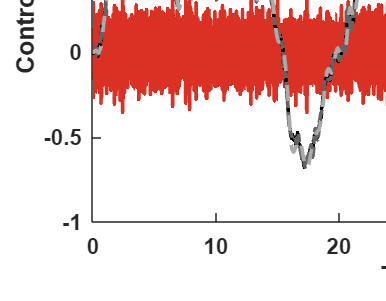

%% 控制力对比图
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.Position = [1.75 1.5 14 8];

nexttile;
hold on;
p4 = plot(out.tout,out.u_PROPOSE,'r','LineWidth',2,'Color',[219, 49, 36, 0.7*255]/255);
p3 = plot(out.tout,out.u_OF,'k-','LineWidth',2);
p2 = plot(out.tout,out.u_ADRC,'k-.','LineWidth',2,'Color',[100,100,100]/255);
p1 = plot(out.tout,out.u_PID,'k--','LineWidth',2,'Color',[170,170,170,0.7*255]/255);

xlabel('Time (second)','FontWeight','bold');
ylabel('Control (V)','FontWeight','bold');
legend([p1, p2, p3, p4],'PID','ADRC','DOFC','Proposed Method',...
    'box','off','Orientation','horizontal','Location','northoutside');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures1', 'control effort.pdf'),'ContentType','vector');

% 扰动
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
hold on;
p1 = plot(out.tout,out.dreal,'k','LineWidth',2);

ylim([0 300]);
xlabel('Time (second)','FontWeight','bold');
ylabel('Torque (N·m)','FontWeight','bold');
legend('Wind disturbance','box','off');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;
f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures1', 'disturbance.pdf'),'ContentType','vector');